## **4. Fábrica com defeito em 30% com 5 amostras**

## a)  Por simulação

p = 0.3;
n = 5;
N =1e5;

    **i) Função massa**

pecas = rand(n,N);
menos = pecas <= p;
defeitos = sum(menos);

%amostragem
x = 0:n;

%probabilidades
zero = sum(defeitos==0)

zero = 16618

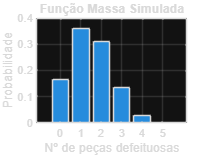

uma = sum(defeitos==1);
duas = sum(defeitos==2);
tres = sum(defeitos==3);
quatro = sum(defeitos==4);
cinco = sum(defeitos==5);

probabilidades = [zero,uma,duas,tres,quatro,cinco]/N;

bar(probabilidades);
xticklabels(x);
title('Função Massa Simulada');
xlabel('Nº de peças defeituosas');
ylabel('Probabilidade');
grid on;

    **ii) Função acumulada**

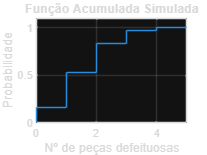

cdf = cumsum(probabilidades);

stairs([0, x , 5.2] , [0 cdf 1.1]);
axis([0,5,0,1.1])
grid on
title('Função Acumulada Simulada');
xlabel('Nº de peças defeituosas');
ylabel('Probabilidade');

    **iii) Máximo 2 peças**

fprintf('A probabilidade de no maximo 2 das peças é %.4f', sum(probabilidades(1:3)));

A probabilidade de no maximo 2 das peças é 0.8355

## b) Analiticamente

   como o numero de tentativas é fixo e só há sucesso ou falha

    a distribuição vai ser bilinear

    **i) Acumulada**

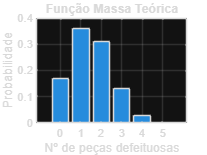

k = 0:5;
distribuicao = zeros(1,length(k));

for i = 1:length(k)
    %calcular coeficiente
    choose = factorial(n)/(factorial(k(i))*factorial(n-k(i)));
    %prob
    probabilidade_t = choose * (p^k(i)) * ((1-p)^(n-k(i)));
    probabilidade_b = d_binomial(k(i), n,p); %teste se d_binomial funciona aprovado
    distribuicao(i) = probabilidade_b;

end

bar(distribuicao);
xticklabels(x);
title('Função Massa Teórica');
xlabel('Nº de peças defeituosas');
ylabel('Probabilidade');
grid on;

   ** ii)Máximo 2 peças**

fprintf('A probabilidade de no maximo 2 das peças é %.4f', sum(distribuicao(1:3)));

A probabilidade de no maximo 2 das peças é 0.8369